# Setup

## Set Parameters for Chronux 

% Setting parameters
params.Fs = 1000; %Sampling frequency of input data (1000 = 1000 hz = 1 sample per millisecond)
params.fpass = [0 100]; % Which frequencies to look at [lowest_wanted highest_wanted]
params.pad = 0; % will add 0's to fit into a power of 2 for better calculation (0 is default and adds 0's to the next power of 2)
TW = 5; % the time-bandwidth product 
K = 9; % the number of tapers, K = 2*TW - 1 
params.tapers = [TW K]; 
params.err = [2 0.05]

params = struct with fields:
        Fs: 1000
     fpass: [0 100]
       pad: 0
    tapers: [5 9]
       err: [2 0.0500]


## Set General Parameters

Gparams.window = 20

Gparams = struct with fields:
    window: 20


Gparams.movingwin = [20 1]

Gparams = struct with fields:
       window: 20
    movingwin: [20 1]


Gparams.alpha = 0.9965

Gparams = struct with fields:
       window: 20
    movingwin: [20 1]
        alpha: 0.9965


Gparams.standardized_len= 0

Gparams = struct with fields:
              window: 20
           movingwin: [20 1]
               alpha: 0.9965
    standardized_len: 0


Gparams.artifact_filter_limit = 0.5

Gparams = struct with fields:
                   window: 20
                movingwin: [20 1]
                    alpha: 0.9965
         standardized_len: 0
    artifact_filter_limit: 0.5000



% Set Bounds for Band Extraction to look at particular band power with function band_extract()
Gparams.extract_lower_bound = 7

Gparams = struct with fields:
                   window: 20
                movingwin: [20 1]
                    alpha: 0.9965
         standardized_len: 0
    artifact_filter_limit: 0.5000
      extract_lower_bound: 7


Gparams.extract_upper_bound = 9

Gparams = struct with fields:
                   window: 20
                movingwin: [20 1]
                    alpha: 0.9965
         standardized_len: 0
    artifact_filter_limit: 0.5000
      extract_lower_bound: 7
      extract_upper_bound: 9



Gparams.segave = 1 % 1 to compute seg average per window in spectrum ; 0 to not average spectrum

Gparams = struct with fields:
                   window: 20
                movingwin: [20 1]
                    alpha: 0.9965
         standardized_len: 0
    artifact_filter_limit: 0.5000
      extract_lower_bound: 7
      extract_upper_bound: 9
                   segave: 1



Gparams.error_bars_01 = 1
Gparams.plot_individual_01 = 1
Gparams.plot_spectrums_together = 1
Gparams.plot_trial_averages = 1

fields = 8×1 cell array
    {'trial_1'}
    {'trial_2'}
    {'trial_3'}
    {'trial_4'}
    {'trial_5'}
    {'trial_6'}
    {'trial_7'}
    {'trial_8'}


current_trial = struct with fields:
                 raw: [1890190×2 single]
            filtered: [1872965×2 single]
         spectrogram: {[1853×3277 double]  [1×1853 double]  [1×3277 double]  [2×1853×3277 double]}
            spectrum: {[3277×1 single]  [1×3277 double]  [3277×1 single]  [3277×3277 single]  [2×3277 double]}
        running_bool: [1×1872 double]
    velocity_per_sec: [1×1872 double]
            distance: [1×1872 double]


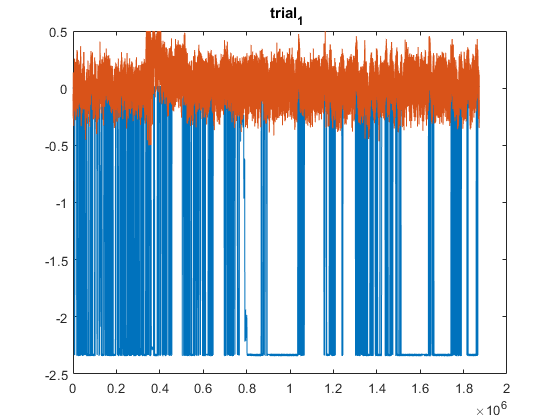

  Columns 1 through 3

    [1853×3277 double]    [1×1853 double]    [1×3277 double]

  Column 4

    [2×1853×3277 double]



s =     0.0108    0.0111    0.0108    0.0101    0.0109    0.0073    0.0081    0.0052    0.0054    0.0028    0.0032    0.0015    0.0008    0.0007    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0004    0.0005    0.0004    0.0005    0.0002    0.0002    0.0002    0.0002    0.0003    0.0002    0.0003    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0124    0.0127    0.0127    0.0120    0.0125    0.0089    0.0092    0.0055    0.0059    0.0027    0.0032    0.0014    0.0011    0.0006    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0004    0.0005    0.0005    0.0004    0.0004    0.0003    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0002    0.0003    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0

t = 	1.0e+03 *

    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500    0.0510    0.0520    0.0530    0.0540    0.0550    0.0560    0.0570    0.0580    0.0590


f =          0    0.0305    0.0610    0.0916    0.1221    0.1526    0.1831    0.2136    0.2441    0.2747    0.3052    0.3357    0.3662    0.3967    0.4272    0.4578    0.4883    0.5188    0.5493    0.5798    0.6104    0.6409    0.6714    0.7019    0.7324    0.7629    0.7935    0.8240    0.8545    0.8850    0.9155    0.9460    0.9766    1.0071    1.0376    1.0681    1.0986    1.1292    1.1597    1.1902    1.2207    1.2512    1.2817    1.3123    1.3428    1.3733    1.4038    1.4343    1.4648    1.4954


Serr = Serr(:,:,1) =

  Columns 1 through 999

    0.0035    0.0025    0.0047    0.0062    0.0065    0.0059    0.0049    0.0030    0.0008    0.0001    0.0000    0.0004    0.0023    0.0041    0.0045    0.0039    0.0058    0.0053    0.0046    0.0046    0.0029    0.0040    0.0021    0.0024    0.0029    0.0018    0.0003    0.0003    0.0020    0.0031    0.0030    0.0035    0.0031    0.0024    0.0027    0.0015    0.0026    0.0032    0.0059    0.0075    0.0090    0.0090    0.0068    0.0034    0.0017    0.0026    0.0022    0.0009    0.0013    0.0033    0.0063    0.0061    0.0041    0.0058    0.0107    0.0125    0.0093    0.0048    0.0035    0.0031    0.0023    0.0010    0.0020    0.0038    0.0045    0.0051    0.0068    0.0058    0.0037    0.0021    0.0026    0.0032    0.0016    0.0005    0.0008    0.0015    0.0027    0.0050    0.0071    0.0061    0.0059    0.0062    0.0060    0.0048    0.0049    0.0036    0.0013    0.0016    0.0036    0.0043    0.0080    0.0096    0.0063    0.0050    0.0073   

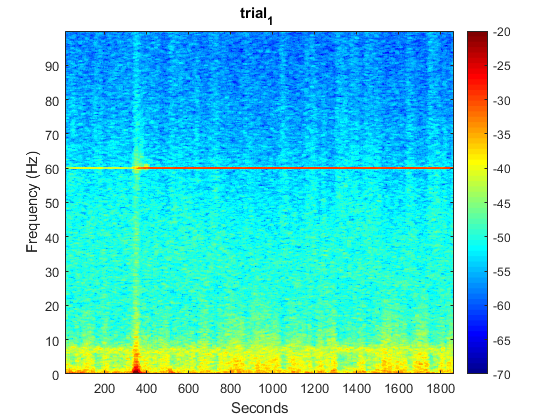

current_trial = struct with fields:
                 raw: [3689071×2 single]
            filtered: [3610252×2 single]
         spectrogram: {[3591×3277 double]  [1×3591 double]  [1×3277 double]  [2×3591×3277 double]}
            spectrum: {[3277×1 single]  [1×3277 double]  [3277×1 single]  [3277×3277 single]  [2×3277 double]}
        running_bool: [1×3610 double]
    velocity_per_sec: [1×3610 double]
            distance: [1×3610 double]


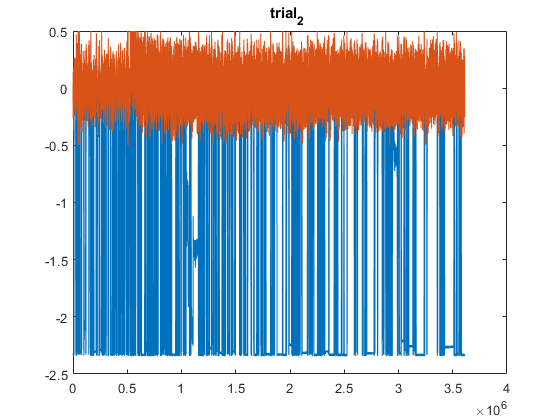

  Columns 1 through 3

    [3591×3277 double]    [1×3591 double]    [1×3277 double]

  Column 4

    [2×3591×3277 double]



s =     0.0091    0.0093    0.0093    0.0089    0.0083    0.0080    0.0075    0.0051    0.0049    0.0039    0.0022    0.0020    0.0016    0.0008    0.0007    0.0007    0.0007    0.0005    0.0005    0.0005    0.0006    0.0005    0.0005    0.0005    0.0005    0.0004    0.0004    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004
    0.0090    0.0091    0.0091    0.0088    0.0083    0.0078    0.0073    0.0047    0.0047    0.0035    0.0021    0.0020    0.0015    0.0008    0.0007    0.0007    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0004    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0002    0.0002    0.0002    0.0002    0.0003    0.0002    0.0003    0.0003    0.0004    0.0004    0.0004    0

t = 	1.0e+03 *

    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500    0.0510    0.0520    0.0530    0.0540    0.0550    0.0560    0.0570    0.0580    0.0590


f =          0    0.0305    0.0610    0.0916    0.1221    0.1526    0.1831    0.2136    0.2441    0.2747    0.3052    0.3357    0.3662    0.3967    0.4272    0.4578    0.4883    0.5188    0.5493    0.5798    0.6104    0.6409    0.6714    0.7019    0.7324    0.7629    0.7935    0.8240    0.8545    0.8850    0.9155    0.9460    0.9766    1.0071    1.0376    1.0681    1.0986    1.1292    1.1597    1.1902    1.2207    1.2512    1.2817    1.3123    1.3428    1.3733    1.4038    1.4343    1.4648    1.4954


Serr = Serr(:,:,1) =

  Columns 1 through 999

    0.0031    0.0021    0.0013    0.0044    0.0047    0.0036    0.0030    0.0025    0.0035    0.0027    0.0029    0.0058    0.0095    0.0094    0.0091    0.0090    0.0083    0.0062    0.0061    0.0046    0.0023    0.0010    0.0020    0.0033    0.0056    0.0089    0.0078    0.0080    0.0155    0.0147    0.0181    0.0174    0.0252    0.0176    0.0151    0.0127    0.0050    0.0069    0.0132    0.0071    0.0086    0.0224    0.0212    0.0216    0.0220    0.0148    0.0169    0.0291    0.0228    0.0181    0.0121    0.0078    0.0106    0.0115    0.0072    0.0064    0.0080    0.0113    0.0111    0.0094    0.0090    0.0106    0.0056    0.0018    0.0027    0.0051    0.0036    0.0022    0.0027    0.0037    0.0040    0.0056    0.0054    0.0052    0.0044    0.0052    0.0045    0.0046    0.0039    0.0030    0.0019    0.0028    0.0034    0.0049    0.0046    0.0049    0.0053    0.0041    0.0021    0.0020    0.0020    0.0009    0.0003    0.0006    0.0021   

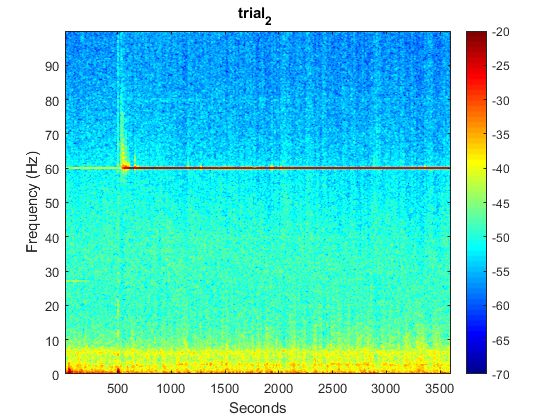

current_trial = struct with fields:
                 raw: [3517539×2 single]
            filtered: [3517509×2 single]
         spectrogram: {[3498×3277 double]  [1×3498 double]  [1×3277 double]  [2×3498×3277 double]}
            spectrum: {[3277×1 single]  [1×3277 double]  [3277×1 single]  [3277×3277 single]  [2×3277 double]}
        running_bool: [1×3517 double]
    velocity_per_sec: [1×3517 double]
            distance: [1×3517 double]


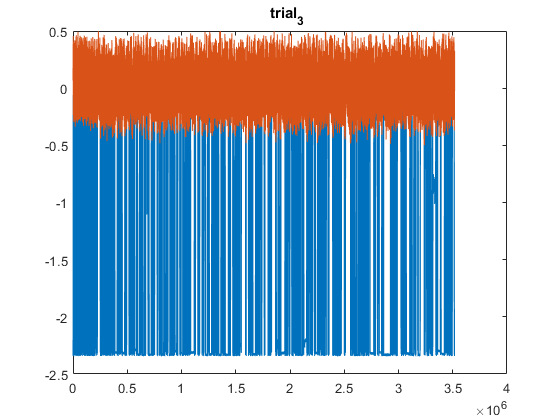

  Columns 1 through 3

    [3498×3277 double]    [1×3498 double]    [1×3277 double]

  Column 4

    [2×3498×3277 double]



s =     0.0127    0.0119    0.0124    0.0125    0.0119    0.0124    0.0095    0.0107    0.0030    0.0015    0.0008    0.0005    0.0004    0.0003    0.0004    0.0002    0.0003    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001    0.0000    0.0001    0.0001    0.0001
    0.0113    0.0103    0.0106    0.0103    0.0103    0.0105    0.0084    0.0095    0.0028    0.0012    0.0007    0.0005    0.0004    0.0004    0.0004    0.0003    0.0003    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000    0.0001    0

t = 	1.0e+03 *

    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500    0.0510    0.0520    0.0530    0.0540    0.0550    0.0560    0.0570    0.0580    0.0590


f =          0    0.0305    0.0610    0.0916    0.1221    0.1526    0.1831    0.2136    0.2441    0.2747    0.3052    0.3357    0.3662    0.3967    0.4272    0.4578    0.4883    0.5188    0.5493    0.5798    0.6104    0.6409    0.6714    0.7019    0.7324    0.7629    0.7935    0.8240    0.8545    0.8850    0.9155    0.9460    0.9766    1.0071    1.0376    1.0681    1.0986    1.1292    1.1597    1.1902    1.2207    1.2512    1.2817    1.3123    1.3428    1.3733    1.4038    1.4343    1.4648    1.4954


Serr = Serr(:,:,1) =

  Columns 1 through 999

    0.0065    0.0059    0.0047    0.0034    0.0024    0.0018    0.0014    0.0014    0.0015    0.0021    0.0026    0.0024    0.0026    0.0032    0.0032    0.0029    0.0026    0.0025    0.0024    0.0024    0.0024    0.0022    0.0022    0.0025    0.0034    0.0043    0.0058    0.0061    0.0050    0.0039    0.0038    0.0033    0.0019    0.0008    0.0004    0.0004    0.0009    0.0019    0.0031    0.0041    0.0054    0.0063    0.0057    0.0054    0.0053    0.0055    0.0058    0.0064    0.0062    0.0050    0.0037    0.0023    0.0015    0.0012    0.0015    0.0020    0.0028    0.0039    0.0056    0.0067    0.0065    0.0062    0.0064    0.0069    0.0067    0.0051    0.0045    0.0040    0.0033    0.0027    0.0025    0.0026    0.0026    0.0022    0.0025    0.0035    0.0045    0.0042    0.0036    0.0034    0.0041    0.0044    0.0035    0.0027    0.0026    0.0026    0.0026    0.0024    0.0031    0.0032    0.0026    0.0039    0.0046    0.0044    0.0041   

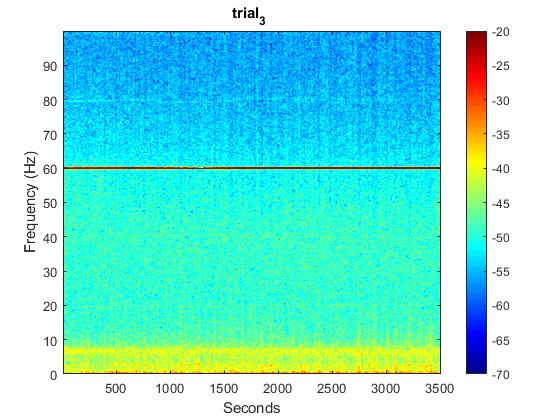

current_trial = struct with fields:
                 raw: [3770358×2 single]
            filtered: [3769937×2 single]
         spectrogram: {[3750×3277 double]  [1×3750 double]  [1×3277 double]  [2×3750×3277 double]}
            spectrum: {[3277×1 single]  [1×3277 double]  [3277×1 single]  [3277×3277 single]  [2×3277 double]}
        running_bool: [1×3769 double]
    velocity_per_sec: [1×3769 double]
            distance: [1×3769 double]


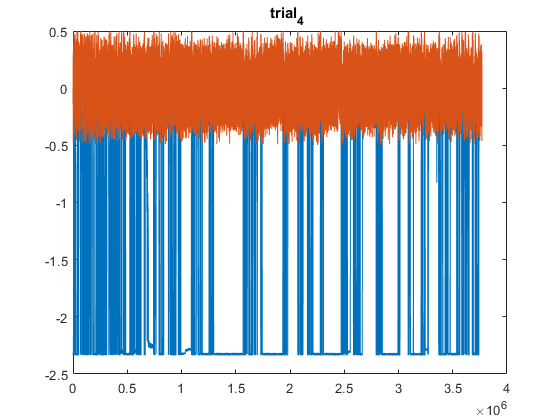

  Columns 1 through 3

    [3750×3277 double]    [1×3750 double]    [1×3277 double]

  Column 4

    [2×3750×3277 double]



s =     0.0211    0.0217    0.0209    0.0200    0.0205    0.0172    0.0171    0.0124    0.0100    0.0044    0.0039    0.0011    0.0010    0.0009    0.0006    0.0008    0.0007    0.0007    0.0008    0.0006    0.0007    0.0005    0.0006    0.0006    0.0005    0.0005    0.0004    0.0004    0.0003    0.0003    0.0002    0.0002    0.0002    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002
    0.0221    0.0224    0.0221    0.0211    0.0210    0.0177    0.0173    0.0145    0.0101    0.0044    0.0046    0.0011    0.0012    0.0005    0.0005    0.0005    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0003    0.0004    0.0003    0.0003    0.0003    0.0002    0.0002    0.0002    0.0002    0.0001    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0

t = 	1.0e+03 *

    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500    0.0510    0.0520    0.0530    0.0540    0.0550    0.0560    0.0570    0.0580    0.0590


f =          0    0.0305    0.0610    0.0916    0.1221    0.1526    0.1831    0.2136    0.2441    0.2747    0.3052    0.3357    0.3662    0.3967    0.4272    0.4578    0.4883    0.5188    0.5493    0.5798    0.6104    0.6409    0.6714    0.7019    0.7324    0.7629    0.7935    0.8240    0.8545    0.8850    0.9155    0.9460    0.9766    1.0071    1.0376    1.0681    1.0986    1.1292    1.1597    1.1902    1.2207    1.2512    1.2817    1.3123    1.3428    1.3733    1.4038    1.4343    1.4648    1.4954


Serr = Serr(:,:,1) =

  Columns 1 through 999

    0.0049    0.0067    0.0096    0.0088    0.0070    0.0055    0.0073    0.0103    0.0065    0.0029    0.0012    0.0010    0.0016    0.0031    0.0040    0.0047    0.0065    0.0085    0.0067    0.0044    0.0034    0.0035    0.0058    0.0104    0.0136    0.0158    0.0198    0.0200    0.0158    0.0101    0.0042    0.0011    0.0002    0.0003    0.0017    0.0059    0.0116    0.0154    0.0161    0.0179    0.0168    0.0110    0.0067    0.0075    0.0059    0.0022    0.0001    0.0002    0.0009    0.0014    0.0023    0.0045    0.0080    0.0121    0.0147    0.0149    0.0175    0.0195    0.0172    0.0130    0.0066    0.0018    0.0004    0.0003    0.0012    0.0052    0.0120    0.0146    0.0175    0.0199    0.0160    0.0143    0.0150    0.0136    0.0100    0.0075    0.0049    0.0023    0.0016    0.0018    0.0032    0.0047    0.0047    0.0048    0.0069    0.0096    0.0086    0.0071    0.0095    0.0099    0.0054    0.0020    0.0023    0.0032    0.0013   

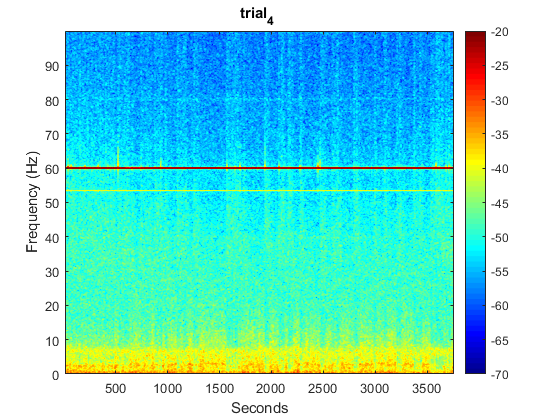

current_trial = struct with fields:
                 raw: [3691845×2 single]
            filtered: [3691467×2 single]
         spectrogram: {[3672×3277 double]  [1×3672 double]  [1×3277 double]  [2×3672×3277 double]}
            spectrum: {[3277×1 single]  [1×3277 double]  [3277×1 single]  [3277×3277 single]  [2×3277 double]}
        running_bool: [1×3691 double]
    velocity_per_sec: [1×3691 double]
            distance: [1×3691 double]


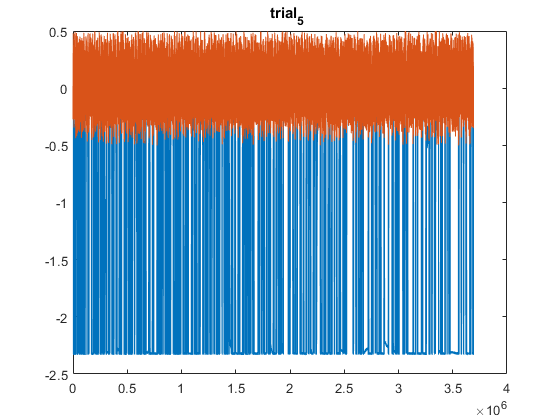

  Columns 1 through 3

    [3672×3277 double]    [1×3672 double]    [1×3277 double]

  Column 4

    [2×3672×3277 double]



s =     0.0139    0.0138    0.0136    0.0138    0.0126    0.0132    0.0100    0.0106    0.0038    0.0023    0.0010    0.0008    0.0003    0.0003    0.0001    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0167    0.0155    0.0162    0.0159    0.0147    0.0155    0.0117    0.0129    0.0041    0.0028    0.0007    0.0009    0.0001    0.0003    0.0002    0.0001    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0

t = 	1.0e+03 *

    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500    0.0510    0.0520    0.0530    0.0540    0.0550    0.0560    0.0570    0.0580    0.0590


f =          0    0.0305    0.0610    0.0916    0.1221    0.1526    0.1831    0.2136    0.2441    0.2747    0.3052    0.3357    0.3662    0.3967    0.4272    0.4578    0.4883    0.5188    0.5493    0.5798    0.6104    0.6409    0.6714    0.7019    0.7324    0.7629    0.7935    0.8240    0.8545    0.8850    0.9155    0.9460    0.9766    1.0071    1.0376    1.0681    1.0986    1.1292    1.1597    1.1902    1.2207    1.2512    1.2817    1.3123    1.3428    1.3733    1.4038    1.4343    1.4648    1.4954


Serr = Serr(:,:,1) =

  Columns 1 through 999

    0.0054    0.0078    0.0095    0.0076    0.0050    0.0034    0.0021    0.0010    0.0006    0.0014    0.0043    0.0049    0.0050    0.0070    0.0030    0.0022    0.0061    0.0077    0.0058    0.0070    0.0038    0.0044    0.0049    0.0046    0.0037    0.0004    0.0005    0.0040    0.0049    0.0060    0.0033    0.0019    0.0014    0.0005    0.0008    0.0016    0.0019    0.0021    0.0014    0.0014    0.0014    0.0008    0.0009    0.0010    0.0014    0.0013    0.0012    0.0017    0.0009    0.0010    0.0006    0.0008    0.0023    0.0021    0.0018    0.0020    0.0004    0.0020    0.0033    0.0025    0.0026    0.0022    0.0022    0.0026    0.0016    0.0015    0.0025    0.0011    0.0017    0.0030    0.0019    0.0028    0.0017    0.0013    0.0024    0.0019    0.0023    0.0006    0.0010    0.0019    0.0032    0.0034    0.0040    0.0029    0.0046    0.0046    0.0045    0.0051    0.0036    0.0018    0.0006    0.0004    0.0009    0.0024    0.0022   

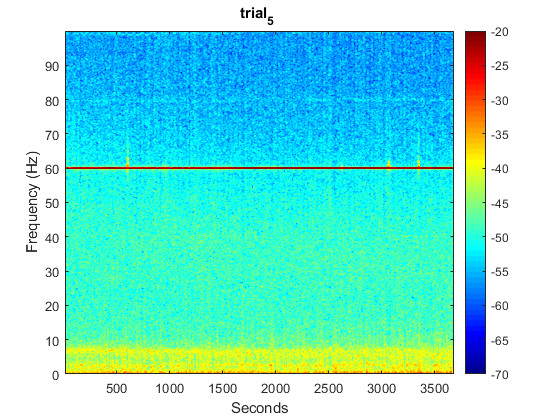

current_trial = struct with fields:
                 raw: [3938323×2 single]
            filtered: [3935536×2 single]
         spectrogram: {[3916×3277 double]  [1×3916 double]  [1×3277 double]  [2×3916×3277 double]}
            spectrum: {[3277×1 single]  [1×3277 double]  [3277×1 single]  [3277×3277 single]  [2×3277 double]}
        running_bool: [1×3935 double]
    velocity_per_sec: [1×3935 double]
            distance: [1×3935 double]


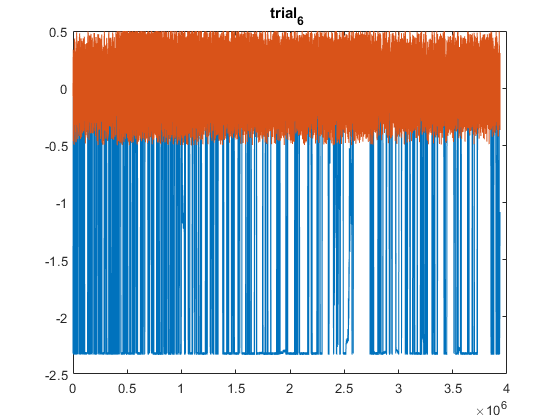

  Columns 1 through 3

    [3916×3277 double]    [1×3916 double]    [1×3277 double]

  Column 4

    [2×3916×3277 double]



s =     0.0118    0.0117    0.0117    0.0117    0.0118    0.0113    0.0109    0.0073    0.0056    0.0035    0.0016    0.0007    0.0003    0.0004    0.0004    0.0003    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0111    0.0112    0.0112    0.0112    0.0111    0.0111    0.0097    0.0064    0.0054    0.0036    0.0014    0.0005    0.0003    0.0003    0.0003    0.0003    0.0002    0.0003    0.0002    0.0003    0.0002    0.0003    0.0002    0.0002    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0

t = 	1.0e+03 *

    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500    0.0510    0.0520    0.0530    0.0540    0.0550    0.0560    0.0570    0.0580    0.0590


f =          0    0.0305    0.0610    0.0916    0.1221    0.1526    0.1831    0.2136    0.2441    0.2747    0.3052    0.3357    0.3662    0.3967    0.4272    0.4578    0.4883    0.5188    0.5493    0.5798    0.6104    0.6409    0.6714    0.7019    0.7324    0.7629    0.7935    0.8240    0.8545    0.8850    0.9155    0.9460    0.9766    1.0071    1.0376    1.0681    1.0986    1.1292    1.1597    1.1902    1.2207    1.2512    1.2817    1.3123    1.3428    1.3733    1.4038    1.4343    1.4648    1.4954


Serr = Serr(:,:,1) =

  Columns 1 through 999

    0.0032    0.0012    0.0007    0.0020    0.0058    0.0075    0.0052    0.0038    0.0045    0.0033    0.0027    0.0026    0.0023    0.0031    0.0034    0.0031    0.0027    0.0027    0.0035    0.0045    0.0037    0.0012    0.0005    0.0011    0.0030    0.0026    0.0022    0.0018    0.0023    0.0030    0.0031    0.0031    0.0021    0.0025    0.0021    0.0020    0.0021    0.0012    0.0013    0.0004    0.0012    0.0020    0.0027    0.0026    0.0035    0.0032    0.0048    0.0041    0.0021    0.0014    0.0021    0.0014    0.0006    0.0005    0.0013    0.0029    0.0029    0.0034    0.0050    0.0038    0.0030    0.0042    0.0036    0.0031    0.0041    0.0015    0.0023    0.0025    0.0021    0.0013    0.0001    0.0009    0.0027    0.0024    0.0032    0.0036    0.0014    0.0017    0.0025    0.0015    0.0017    0.0024    0.0025    0.0031    0.0044    0.0052    0.0017    0.0008    0.0025    0.0037    0.0032    0.0020    0.0012    0.0009    0.0014   

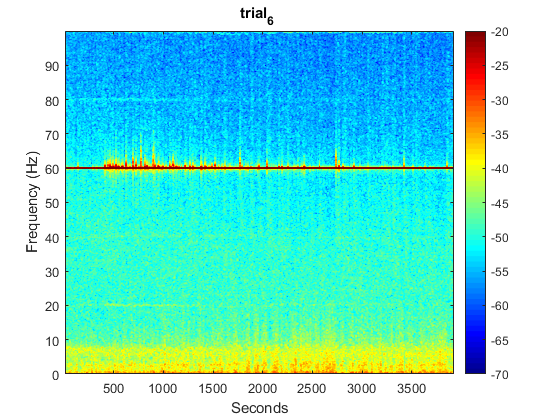

current_trial = struct with fields:
                 raw: [3639901×2 single]
            filtered: [3544489×2 single]
         spectrogram: {[3525×3277 double]  [1×3525 double]  [1×3277 double]  [2×3525×3277 double]}
            spectrum: {[3277×1 single]  [1×3277 double]  [3277×1 single]  [3277×3277 single]  [2×3277 double]}
        running_bool: [1×3544 double]
    velocity_per_sec: [1×3544 double]
            distance: [1×3544 double]


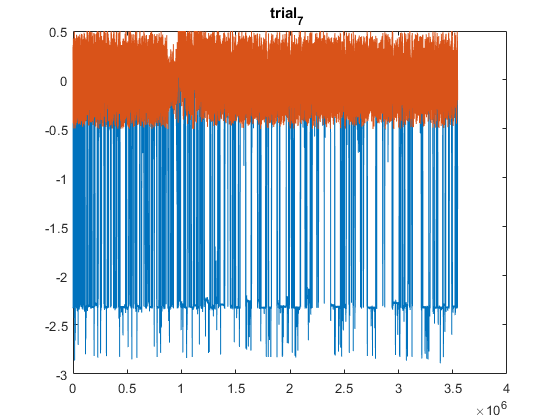

  Columns 1 through 3

    [3525×3277 double]    [1×3525 double]    [1×3277 double]

  Column 4

    [2×3525×3277 double]



s =     0.0066    0.0066    0.0066    0.0064    0.0060    0.0051    0.0035    0.0039    0.0025    0.0024    0.0018    0.0007    0.0003    0.0003    0.0003    0.0002    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0082    0.0077    0.0080    0.0080    0.0077    0.0068    0.0046    0.0047    0.0031    0.0028    0.0020    0.0007    0.0003    0.0003    0.0003    0.0002    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0002    0.0001    0.0001    0.0001    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0

t = 	1.0e+03 *

    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500    0.0510    0.0520    0.0530    0.0540    0.0550    0.0560    0.0570    0.0580    0.0590


f =          0    0.0305    0.0610    0.0916    0.1221    0.1526    0.1831    0.2136    0.2441    0.2747    0.3052    0.3357    0.3662    0.3967    0.4272    0.4578    0.4883    0.5188    0.5493    0.5798    0.6104    0.6409    0.6714    0.7019    0.7324    0.7629    0.7935    0.8240    0.8545    0.8850    0.9155    0.9460    0.9766    1.0071    1.0376    1.0681    1.0986    1.1292    1.1597    1.1902    1.2207    1.2512    1.2817    1.3123    1.3428    1.3733    1.4038    1.4343    1.4648    1.4954


Serr = Serr(:,:,1) =

  Columns 1 through 999

    0.0032    0.0042    0.0031    0.0019    0.0019    0.0020    0.0010    0.0014    0.0009    0.0005    0.0009    0.0019    0.0027    0.0023    0.0017    0.0025    0.0026    0.0028    0.0024    0.0017    0.0008    0.0003    0.0003    0.0004    0.0003    0.0002    0.0004    0.0004    0.0003    0.0002    0.0006    0.0006    0.0004    0.0008    0.0006    0.0008    0.0003    0.0007    0.0006    0.0002    0.0003    0.0007    0.0004    0.0006    0.0009    0.0007    0.0009    0.0008    0.0007    0.0004    0.0003    0.0015    0.0009    0.0011    0.0011    0.0009    0.0015    0.0020    0.0018    0.0023    0.0017    0.0005    0.0004    0.0015    0.0035    0.0035    0.0025    0.0030    0.0027    0.0014    0.0016    0.0017    0.0013    0.0012    0.0013    0.0017    0.0016    0.0009    0.0006    0.0013    0.0016    0.0026    0.0017    0.0012    0.0020    0.0019    0.0008    0.0007    0.0010    0.0009    0.0009    0.0004    0.0005    0.0015    0.0022   

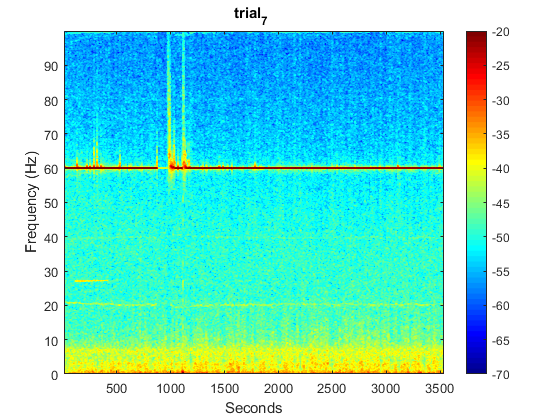

current_trial = struct with fields:
                 raw: [3861380×2 single]
            filtered: [3847189×2 single]
         spectrogram: {[3828×3277 double]  [1×3828 double]  [1×3277 double]  [2×3828×3277 double]}
            spectrum: {[3277×1 single]  [1×3277 double]  [3277×1 single]  [3277×3277 single]  [2×3277 double]}
        running_bool: [1×3847 double]
    velocity_per_sec: [1×3847 double]
            distance: [1×3847 double]


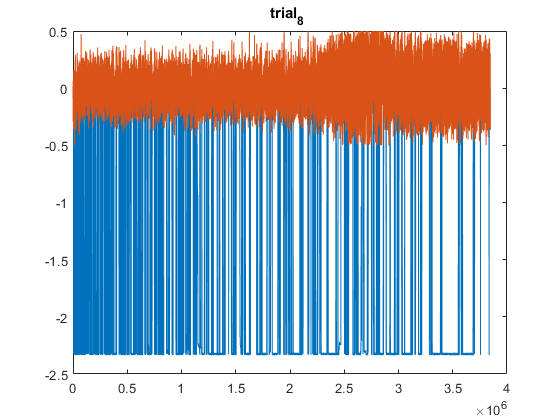

  Columns 1 through 3

    [3828×3277 double]    [1×3828 double]    [1×3277 double]

  Column 4

    [2×3828×3277 double]



s =     0.0282    0.0286    0.0285    0.0276    0.0270    0.0252    0.0219    0.0219    0.0128    0.0065    0.0067    0.0030    0.0026    0.0019    0.0016    0.0016    0.0013    0.0009    0.0008    0.0008    0.0007    0.0006    0.0006    0.0005    0.0005    0.0004    0.0004    0.0003    0.0003    0.0003    0.0003    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002
    0.0279    0.0274    0.0278    0.0263    0.0264    0.0242    0.0205    0.0211    0.0120    0.0065    0.0072    0.0030    0.0028    0.0018    0.0016    0.0015    0.0013    0.0010    0.0008    0.0008    0.0007    0.0007    0.0006    0.0005    0.0005    0.0005    0.0004    0.0004    0.0003    0.0003    0.0003    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0

t = 	1.0e+03 *

    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500    0.0510    0.0520    0.0530    0.0540    0.0550    0.0560    0.0570    0.0580    0.0590


f =          0    0.0305    0.0610    0.0916    0.1221    0.1526    0.1831    0.2136    0.2441    0.2747    0.3052    0.3357    0.3662    0.3967    0.4272    0.4578    0.4883    0.5188    0.5493    0.5798    0.6104    0.6409    0.6714    0.7019    0.7324    0.7629    0.7935    0.8240    0.8545    0.8850    0.9155    0.9460    0.9766    1.0071    1.0376    1.0681    1.0986    1.1292    1.1597    1.1902    1.2207    1.2512    1.2817    1.3123    1.3428    1.3733    1.4038    1.4343    1.4648    1.4954


Serr = Serr(:,:,1) =

  Columns 1 through 999

    0.0089    0.0109    0.0137    0.0074    0.0029    0.0019    0.0040    0.0053    0.0026    0.0044    0.0057    0.0043    0.0069    0.0104    0.0089    0.0056    0.0040    0.0019    0.0014    0.0028    0.0029    0.0029    0.0022    0.0018    0.0033    0.0028    0.0014    0.0008    0.0012    0.0011    0.0017    0.0015    0.0018    0.0028    0.0031    0.0031    0.0027    0.0017    0.0012    0.0013    0.0008    0.0008    0.0012    0.0026    0.0035    0.0018    0.0023    0.0019    0.0024    0.0042    0.0033    0.0040    0.0032    0.0002    0.0004    0.0040    0.0058    0.0060    0.0076    0.0072    0.0059    0.0032    0.0011    0.0018    0.0039    0.0023    0.0021    0.0033    0.0055    0.0065    0.0045    0.0035    0.0046    0.0054    0.0046    0.0020    0.0013    0.0009    0.0012    0.0003    0.0015    0.0012    0.0012    0.0016    0.0015    0.0012    0.0014    0.0011    0.0007    0.0004    0.0005    0.0006    0.0014    0.0021    0.0016   

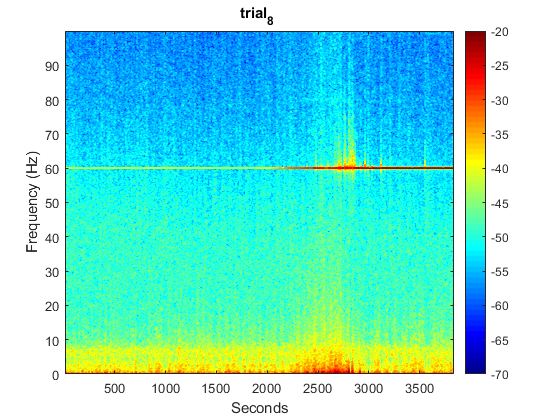

LFP_pp_analysis(knockouts_pp)

plot_spectrum_pp(mean(knockouts_pp.trial_1.spectrum, knockouts_pp.trial_2.spectrum), 1)

Error using sum
Invalid data type. First argument must be numeric or logical.

Error in mean (line 116)
        y = sum(x, dim, flag) ./ size(x,dim);

function result = LFP_pp_analysis(data_struct, Gparams)


% Plot Each Trial Individually
if Gparams.plot_individual_01 == 1

    fields = fieldnames(data_struct)
    for ii = 1:numel(fields)
        
        current_trial = data_struct.(fields{ii})
        
        % Plot Filtered Data
        title_filtered = sprintf('%s %f Filtered Data', fields{ii});
        
        figure; plot (current_trial.filtered); title (title_filtered);
        
        plot_spectrogram(current_trial.spectrogram); title (title_filtered);
        
        
        figure; plot_spectrum_pp (current_trial.spectrum, Gparams.error_bars_01); title (title_filtered);
        
    end
end

if Gparams.plot_spectrums_together_01 == 1
    fields = fieldnames(data_struct)
    figure;
    for ii = 1:numel(fields)
        
        current_trial = data_struct.(fields{ii})
        
        % Plot Spectrums together with hold on
 
        plot_spectrum_pp (current_trial.spectrum, Gparams.error_bars_01); title (title_filtered);
        hold on
    end
   
end

if Gparams.plot_trail_averages_01 == 1
    plot_spectrum_pp(data_struct.average.spectrum, Gparams.error_bars_01)
    
   
    
end

end


## Plot_spectrum_pp

function result = plot_spectrum_pp (pp_spectrum_data, error_bars_01)

if ~exist('error_bars_01', 'var'), error_bars_01 = 0; end


s = pp_spectrum_data{1}
f =pp_spectrum_data{2}
varS = pp_spectrum_data{3}
C = pp_spectrum_data{4}
Serr = pp_spectrum_data{5}

if error_bars_01 == 0 
    plot_vector(s,f, 'l'); title('Spectrum No Error Bars'); ylim([-60 -10]); xlabel('Frequency');

end

if error_bars_01 == 1
    plot_vector(s,f, 'l', Serr); title('Spectrum log scale 20 second average window'); ylim([-60 -10]); xlabel('Frequency');
end

end

## LFP Total Analysis  

function result = LFP_analysis_pp(data_struct, params, Gparams, label, filter_data_01, analyze_running_01, analyze_individual_01, analyze_together_01, analyze_average_01, error_bars_01) 

% Set Default Values
if ~exist('label', 'var'), label = '';end
if ~exist('filter_data_01', 'var'), filter_data_01 = 0; end
if ~exist('analyze_running_01', 'var'), analyze_running_01 = 0; end
if ~exist('analyze_individual_01', 'var'), analyze_individual_01 = 0; end
if ~exist('analyze_together_01', 'var'), analyze_together_01 = 0; end
if ~exist('analyze_average_01', 'var'), analyze_average_01 = 1; end
if ~exist('error_bars_01', 'var'), error_bars_01 = 0; end


fields = fieldnames(data_struct)



% Individual Trial Analysis
if analyze_individual_01 == 1
    for ii = 1:length(cell_array)
        
        % Plot Filtered Data
        
       
        figure; plot(cell_array{ii}); title(title_filtered); 
        plot_spectrum(cell_array{ii}, params, Gparams.window, error_bars_01); title(title_filtered);
        
        
        if analyze_running_01 == 1
            running_data = process_running_data(cell_array{ii});
            percent_running(running_data);
            running_theta(cell_array{ii}, params, Gparams, running_data),title(title_filtered);
           
        elseif analyze_running_01 == 0
            plot_spectrogram(cell_array{ii}, params, Gparams.movingwin); title(title_filtered);
        end
        
        
    end    
end

% Analyze Together - Plot All Spectrums on One Figure
if analyze_together_01 == 1
    plot_spectrum(cell_array, params, Gparams.window, error_bars_01)
end


% Averaged Trial Analysis
if analyze_average_01 == 1
    
    %Averaged Analysis and plotting
    cat = vertcat_cell_array(cell_array);
    
    plot_spectrum(cat, params, Gparams.window);
    
    if analyze_running_01 == 1
        running_data = process_running_data(cat);
        percent_running(running_data);
        running_theta(cat, params, Gparams, running_data); title('Does this Work');
        
    elseif analyze_running_01 == 0
        plot_spectrogram(cat, params, Gparams.movingwin);
    end
    
end


end

# Preprocessing 

## Preprocess Group of LFP Datasets & Assign to Struct

function result = preprocess_LFP_master(cell_array, params, Gparams)
for ii = 1:length(cell_array)
    name = genvarname(sprintf('trial_%g', ii))
    hold_struct.(name) = preprocess_LFP(cell_array{ii}, params, Gparams);
end
result = hold_struct
end

## Preprocess Individual LFP Dataset & Assign to Struct

function result = preprocess_LFP(xarray, params, Gparams)

% Add Raw Data to Struct
raw = xarray;

% Add Filtered Data to Struct
filtered = artifact_filter(xarray, Gparams.artifact_filter_limit);

% Compute Spectrogram Data
[S, t, f, Serr] = mtspecgramc(filtered(:,2), Gparams.movingwin, params);
spectrogram = {S, t, f, Serr};

% Compute Seg Spectrum Data
[S1, f1, varS1, C1, Serr1] = mtspectrumsegc(filtered(:,2), 20 , params, 1);
spectrum = {S1, f1, varS1, C1, Serr1};

%Compute Running Boolean Data
running_bool = process_running_data(filtered(:,1))

% Compute Average Velocity Per Second (cm/s)
velocity_per_sec = velocity_opto(filtered(:,1))

% Compute total distance (cm)
distance = distance_from_velocity(velocity_per_sec)

%%%% leave out theta computation and band extract

result = v2struct(raw, filtered, spectrogram, spectrum, running_bool, velocity_per_sec, distance)
end


# **Functions**

# Analysis

## _____________________________________________________________________________

# Plotting Data

## Calculate and Plot Spectrum Segs 

    - Optional: Show Error Bars, Plot Together/Individually

function result = plot_spectrum(data_struct, error_bars_01, individual_plot_01, segave_01)

% Set default argument values
if ~exist('window', 'var'), window = 20; end % window is length in seconds to average over
if ~exist('error_bars_01', 'var'), error_bars_01 = 0 ; end 
if ~exist ('individual_plot_01', 'var'), individual_plot_01 = 0; end
if ~exist('segave_01', 'var'), segave_01 = 1; end % Segave = 1 means it will average over the provided window

% Pull data from struct





x = [];

% Plot and return values given varous conditions (no error bars / error bars; indivudual/ grouped)
if error_bars_01 == 1
    
    if individual_plot_01 == 0
        figure;
        
        fields = fieldnames (stuct_data)
        for ii = 1:numel(fields)
            currentdata_struct.(fields{ii})
        end
        
        
        
        
        
        
        
        for ii = 1:length (data)
            
            [s,f, ~, ~, Serr]=mtspectrumsegc(data{ii}(:,2),window,params,segave_01);
            plot_vector(s,f, 'l', Serr); title('Spectrum log scale 20 second average window'); ylim([-60 -10]); xlabel('Frequency');
            hold on 
            
            x{ii} = {s, f, Serr} ;
        end
        
    elseif individual_plot_01 == 1
        for ii = 1:length (data)
            [s,f, ~, ~, Serr]=mtspectrumsegc(data{ii}(:,2),window,params,segave_01);
            figure; plot_vector(s,f, 'l', Serr); title('Spectrum log scale 20 second average window'); ylim([-60 -10]); xlabel('Frequency');
                         
            x{ii} = {s, f, Serr} ;
        end
    end
    
elseif error_bars_01 == 0
    if individual_plot_01 == 0
        figure;
        for ii = 1:length (data)
            [s, f] = mtspectrumsegc(data{ii}(:,2),window,params,segave_01);
            
            plot_vector(s, f, 'l'); title('Spectrum log scale 20 second average window'); ylim([-60 -10]); xlabel('Frequency');
            hold on 
            
            x{ii} = {s, f} ;
        end
    elseif individual_plot_01 == 1
        for ii = 1:length (data)
            [s,f]=mtspectrumsegc(data{ii}(:,2),window,params,segave_01);
            
            figure; plot_vector(s,f, 'l'); title('Spectrum log scale 20 second average window'); ylim([-60 -10]); xlabel('Frequency');
                         
            x{ii} = {s, f} ;
        end
    end
end
    
result = x;

end

## Calculate and Plot Spectrogram

function result = plot_spectrogram (pp_spectrogram_data)
disp(pp_spectrogram_data)

s = pp_spectrogram_data{1}
t = pp_spectrogram_data{2}
f = pp_spectrogram_data{3}
Serr = pp_spectrogram_data{4}

figure; plot_matrix(s,t,f, 'l'); colorbar; colormap jet; caxis ([-70 -20]); xlabel('Seconds'); ylabel('Frequency (Hz)');
result = {s, t, f, Serr};
end

## ____________________________________________________

# Filtering and Shaping Data

## Vertically Concatenate Cell Array

function result = vertcat_cell_array(cell_array)
x = cell_array{1};
for ii = 2: length(cell_array)
    x = vertcat(x,cell_array{ii}); 
end
result = x;
end

## Filter out Artifacts (Array)

function result = artifact_filter(array, limit)

array(abs(array(:,2)) >= limit, :) = [];

result = array;
end

## Standardize Length of Arrays

function result = standardize_length(cell_array, len)
% This function takes a cell array (cell_array) containing a set of arrays
% and makes them all the same length (len) from 1 to len
for ii = 1:length(cell_array)
    cell_array{ii} = cell_array{ii}(1:len,:);
end
result = cell_array;
end


## Remove Frequency Band Noise from Cell Array of Datasets

function result = filter_noise(xarray, noiseHz, Fs, alpha)
% This function removes noise from signal with variable alpha and Hz

% Set parameters for filter

omega = 2*pi*noiseHz/Fs; 
num = [1 -2*cos(omega) 1];
den = [1 -2*alpha*cos(omega) alpha*alpha];

xarray (:,2) = filter(num,den,xarray(:,2));

result = xarray;
end

## Remove 60Hz Noise from Cell Array of Datasets

function result = remove60(cell_array, Fs)
% This function removes 60 Hz noise from signal

% Set parameters for filter

%%%%global params.Fs

alpha = 0.998; 
omega = 2*pi*60/Fs; 
num = [1 -2*cos(omega) 1];
den = [1 -2*alpha*cos(omega) alpha*alpha];

for ii = 1:length(cell_array)
    cell_array{ii}(:,2) = (filter(num,den,cell_array{ii}(:,2)));
end
result = cell_array;
end

## Remove 60Hz Noise from Array

function result = remove60_nocell(xarray, Fs, alpha)
% This function removes 60 Hz noise from signal

% Set parameters for filter

% alpha = 0.9975; 
omega = 2*pi*60/Fs; 
num = [1 -2*cos(omega) 1];
den = [1 -2*alpha*cos(omega) alpha*alpha];

xarray (:,2) = filter(num,den,xarray(:,2));

result = xarray;
end  


## ____________________________________________________________________________

# Movement Data Analysis

## Process Running Data into Boolean per Second

function result = process_running_data(LFP_data)

opto = round(LFP_data(:,1));
times = 1:length(opto);

win = 1000; %window in ms to look at opto
winstart = [1:win:length(times)-win]; %index corresponding to the start of each window

locomotion = []; %vector of 0 (not moving) and 1 (moving) for each window (1 sec)
for i = 1:length(winstart)
   m = winstart(i);
   optowin = opto(m:m+(win-1));
   optowinDif = diff(optowin); %will be all 0 if every value in optowin is the same
   if isempty(find(optowinDif,1)) %if optowinDif are all 0's
       locomotion(i) = 0; %0 means not moving
   else
       locomotion(i) = 1; %1 = moving
   end
end
result = locomotion;
end

## Percent Running Time

function result = percent_running(running_data)
result = sum(running_data(:) == 1)/length(running_data);
fprintf ('Percent Time Running = %.01f%% \n', result*100);
end

## Total Time Running (Seconds)

function result = time_running(running_data)
result = sum(running_data(:) == 1);
fprinf ('Total Time Running is %s \n', result)
end

## Extract Band

function result = band_extract(pp_spectrogram_data, Gparams)
z = find(pp_spectrogram_data{3} > Gparams.extract_lower_bound & pp_spectrogram_data{3} < Gparams.extract_upper_bound)

extracted = pp_spectrogram_data{1}(:, z)

extracted_mean = mean (extracted, 2)

plot_vector(extracted_mean, pp_spectrogram_data{2})

result = extracted_mean
end

## Compare Extracted Power to Running State (PP)

function result  = band_running_compare_pp (pp_spectrogram_data, running_times, params, Gparams)

mean_power_per_time = band_extract (ppdata , Gparams.extract_lower_bound, Gparams.extract_upper_bound);

% Remove first and last seconds from running times to match spec data, remove window/2 from each side
running_times = running_times(Gparams.movingwin(1)/2:length(running_times)-Gparams.movingwin(1)/2)

running_power_mean = mean(mean_power_per_time(running_times == 1))
resting_power_mean = mean(mean_power_per_time(running_times == 0))

result = {running_power_mean, resting_power_mean}
end


## Determine Velocity

function result = velocity_opto (opto_data)
clear 'Wheel'

%Define Wheel Statistics
Wheel.Radius  = 11.06; %radus in cm
Wheel.noftabs = 30; %number of tabs
Wheel.circumference = 2*pi*Wheel.Radius;
Wheel.distpertab =Wheel.circumference/(2*Wheel.noftabs); %distance per tab (tabs are evenly spaced and the wheel is split equally) 
Wheel.window = 1000; %window in miliseconds

%Look at derivative of wheel trace 
Wheel.diffSC = diff(opto_data);  %derivative of the square pulses
Wheel.Thresh = 2*std(Wheel.diffSC);

%define likely break points and binarize
Wheel.triggerframes = find(abs(Wheel.diffSC)>=mean(Wheel.diffSC)+Wheel.Thresh); %find where there was probably a change from blocked to open
Wheel.tabtransittimes = zeros(1,length(opto_data)); %make an empty matrix
Wheel.tabtransittimes(Wheel.triggerframes)= 1; %binarize the transitions

%sum transitions over the window
j=1; clear 'Wheel.numbreaks'
for i=1:Wheel.window:length(opto_data)-(Wheel.window)
    Wheel.numbreaks(j) = sum(Wheel.tabtransittimes(i:i+Wheel.window));
    j=j+1;
end

velocity = Wheel.numbreaks * Wheel.distpertab * 1000 / Wheel.window; %gives approximate velocity at ege of wheel

figure; plot(1:length(velocity),velocity)

result = velocity
end

## Calculate Total Distance

function result = distance_from_velocity(velocity_data)
result = cumtrapz(length(velocity_data), velocity_data)
end